# Robust Controller for Spinning Satellite

This example expands on the [MIMO Stability Margins for Spinning Satellite](https://www.mathworks.com/help/robust/ug/mimo-stability-margins-for-spinning-satellite.html) example by designing a robust controller that overcomes the flaws of the "naive" design. 

**Plant Model**

The plant model is the same as described in [MIMO Stability Margins for Spinning Satellite](https://www.mathworks.com/help/robust/ug/mimo-stability-margins-for-spinning-satellite.html).

a = 10;
A = [0 a;-a 0];
B = eye(2);
C = [1 a;-a 1];
D = 0;
Gnom = ss(A,B,C,D);

**Nominal Mixed-Sensitivity Design**

Start with a basic mixed-sensitivity design using [`mixsyn`](https://www.mathworks.com/help/robust/ref/dynamicsystem.mixsyn.html). Pick the weights to achieve good performance while limiting bandwidth and control effort. (See [Mixed-Sensitivity Loop Shaping](https://www.mathworks.com/help/robust/gs/using-mixsyn-for-h-infinity-loop-shaping.html) for details about this technique and how to choose weighting functions.)

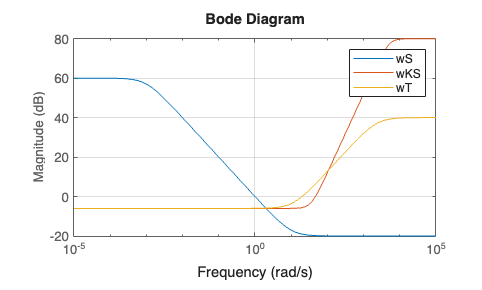

wS = makeweight(1e3,1,1e-1);
wKS = makeweight(0.5,[500 1e2],1e4,0,2);
wT = makeweight(0.5,20,100);
bodemag(wS,wKS,wT)
grid
legend('wS','wKS','wT');